## Data Loading

% clf;clc;clear;

data = load('Data/P2 True Stress (Pa)-Stretch.txt');
stretch = data(:,1);
stress = data(:,2);

## Model Declaration

NeoHookean = @(x, stretch) x.*(stretch.^2 - 1./stretch);
MooneyRivlin = @(x, stretch) 2*(stretch.^2 - 1./stretch).*(x(1) + x(2)./stretch);

I1 = stretch.^2 + 2./stretch;
Yeoh = @(x, stretch) 2*(stretch.^2 - 1./stretch).*(x(1) + 2*x(2).*(I1 - 3) + 3*x(3).*(I1 - 3).^2);
Ogden = @(x, stretch) 2*x(1)./x(2).*(stretch.^(x(2)) - stretch.^(-x(2)/2)) + 2*x(3)./x(4).*(stretch.^(x(4)) - stretch.^(-x(4)/2)) + 2*x(5)./x(6).*(stretch.^(x(6)) - stretch.^(-x(6)/2));
Gent = @(x, stretch) x(1).*(stretch.^2 - 1./stretch).*(x(2)./(x(2) - (stretch.^2 + 2./stretch - 3)));
ET = @(x, stretch) x(1).*(stretch.^2 - 1./stretch).*((1 + (1 + I1.^2 - 4.*I1).*x(2).^2 + (5.*I1 - I1.^2 - 6).*x(2).^4)./(1 - (I1 - 3).*x(2).^2).^2) - 2.*x(3)./x(4).*(stretch.^(-x(4)) - stretch.^(x(4)./2));

% objective function and coefficient of determination
RootMeanSquareDiff = @(x) sqrt(mean((func(x, stretch) - stress).^2)/mean(stress.^2));
coeffDet = @(x, stretch) (1 - sum((func(x, stretch) - stress).^2)/sum((stress - mean(stress)).^2));

functions = [NeoHookean, MooneyRivlin, Yeoh, Ogden, Gent, ET]


## GA Algorithm

func = Ogden;

OgdenFitment = struct('Coeff', zeros(10,6), 'CoeffDet', zeros(10,1));

clf
figure(1)
scatter(stretch, stress, 'DisplayName', 'Data')
xlabel('Stretch')
ylabel('Stress')
legend ('show')
hold on


for i = [1:20]
    i
    % MATLAB GA algorithum --- "Display","iter","PlotFcn","gaplotbestf",
    opts1 = optimoptions("ga", "MaxGenerations", 5000, 'PopulationSize', 500);
    [x, fval, exitflag] = ga(RootMeanSquareDiff, 6,[],[],[],[],[-3e4, 0.9, 1e3, 0.9, -3e4, 0.9],[1e5, 2, 1e5, 3, 1e5, 3],[], opts1);
    
    
    % Least-Square Fitment
    opts2 = optimoptions('lsqcurvefit', 'MaxIterations', 20000, 'MaxFunctionEvaluations', 10000, 'Algorithm', 'levenberg-marquardt');
    [x1, fval] = lsqcurvefit(func, x, stretch, stress, [], [], opts2);
    
    OgdenFitment(i).Coeff = x1;
    OgdenFitment(i).CoeffDet = coeffDet(x1, stretch);
    

    plot(stretch, func(x1, stretch), 'DisplayName', ['Ogden Fit: '+string(i)+', Coeff Det:'+string(OgdenFitment(i).CoeffDet)], 'LineWidth', 2)
    
end

Prony2Term = @(x, time) x(1) + x(2)*exp(-time./x(3)) + x(4)*exp(-time./x(5))

Prony2Term = function_handle with value:
    @(x,time)x(1)+x(2)*exp(-time./x(3))+x(4)*exp(-time./x(5))


RootMeanSquareDiff = @(x) sqrt(mean((Prony2Term(x, Time) - stress).^2)/mean(stress.^2));
clf
stressAvg = mean(stress);

stressAvg = 1.1315e+05


for i = [1:10]
    % MATLAB GA algorithum --- "Display","iter","PlotFcn","gaplotbestf",
    opts1 = optimoptions("ga", "MaxGenerations", 5000, 'PopulationSize', 1000);
    [x, fval, exitflag] = ga(RootMeanSquareDiff, 5,[],[],[],[],[1e4, 1e3, 0.01, 1e4, 1],[1e6, 1e5, 5, 1e6, 10],[], opts1);
        
    
    opts2 = optimoptions('lsqcurvefit', 'MaxIterations', 20000, 'MaxFunctionEvaluations', 10000, 'Algorithm', 'levenberg-marquardt');
    [x, fval] = lsqcurvefit(Prony2Term, x, Time, stress, [1e4, 1e3, 0.01, 1e4, 1], [], opts2);


    r = 1 - (sum(Prony2Term(x, Time) - stress).^2)/sum((stress - mean(stress)).^2)
    
    if r > 0.8
        x
        plot(Time, Prony2Term(x, Time), 'DisplayName', 'Predicted')
        hold on
    end
end

ga stopped because the average change in the fitness value is less than options.FunctionTolerance.



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


r = 0.9997

x = 1.0e+05 *

    1.1138    0.0100    0.0000    0.1000    0.0001


ga stopped because the average change in the fitness value is less than options.FunctionTolerance.



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


r = 0.9999

x = 1.0e+05 *

    1.1225    0.0100    0.0000    0.1000    0.0000


ga stopped because the average change in the fitness value is less than options.FunctionTolerance.



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


r = 0.9999

x = 1.0e+05 *

    1.1225    0.0100    0.0000    0.1000    0.0000


ga stopped because the average change in the fitness value is less than options.FunctionTolerance.



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


r = 0.8701

x = 1.0e+05 *

    1.1192    0.0137    0.0000    0.1000    0.0001


ga stopped because the average change in the fitness value is less than options.FunctionTolerance.



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


r = 0.9999

x = 1.0e+05 *

    1.1225    0.0100    0.0000    0.1000    0.0000


ga stopped because the average change in the fitness value is less than options.FunctionTolerance.



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


r = 0.9994

x = 1.0e+05 *

    1.1226    0.0100    0.0000    0.1000    0.0000


ga stopped because the average change in the fitness value is less than options.FunctionTolerance.



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


r = 0.9995

x = 1.0e+05 *

    1.1226    0.0100    0.0000    0.1000    0.0000


ga stopped because the average change in the fitness value is less than options.FunctionTolerance.



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


r = 0.9995

x = 1.0e+05 *

    1.1226    0.0100    0.0000    0.1000    0.0000


ga stopped because the average change in the fitness value is less than options.FunctionTolerance.



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


r = 0.9995

x = 1.0e+05 *

    1.1226    0.0100    0.0000    0.1000    0.0000


ga stopped because the average change in the fitness value is less than options.FunctionTolerance.



Local minimum found.

Optimization completed because the size of the gradient is less than
1e-4 times the value of the function tolerance.

<stopping criteria details>


r = 1.0000

x = 1.0e+05 *

    1.1192    0.0100    0.0000    0.1000    0.0001


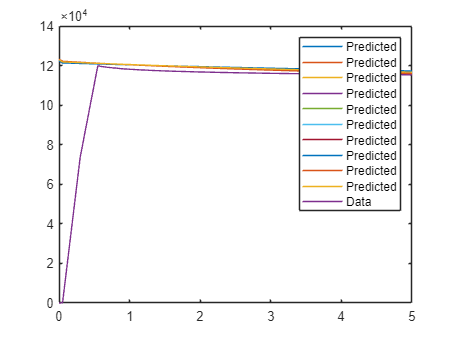

legend show
plot(Time, stress, 'DisplayName', 'Data')
xlim([0,5])